# **CLASIFICACIÓN CON MLP (DEEP LEARNING)**

En este programa se utliza una red neuronal MLP para clasificar patrones. La red se definirá mediante las herramientas de Deep Learning.

El programa clasifica un conjunto de patrones que describen las flores de la planta iris en tres clases.

Los datos proceden de la base de datos Iris de Fisher. En ella las flores de la planta iris se clasifican en tres clases (setosa, versicolor, y virginica) en función de cuatro variables: anchura y longitud de su pétalos y sépalos.

En la dirección [https://es.mathworks.com/help/releases/R2025b/stats/classification-example.html](https://es.mathworks.com/help/releases/R2025b/stats/classification-example.html) se describen varios ejemplos de clasificción realizados con esta base de datos.

En primer lugar se cierran todas las ventana abiertas y se limpian todas las varibles.

close all
clear all 

## **CARGA DE LOS DATOS **

Los datos están guardados en el archivo *fisheriris.mat*, en el que hay dos varibles: *meas* con las medidas y *species* con las clases. *meas* guarda los datos como una matriz de tipo *double* de 150x4 elementos y *species* como un *cell array* de 150x1 valores *character*.

load('fisheriris.mat');
patronEntrada=meas;
claseSalida=species;

Es necesario barajar todas las muestras para eliminar cualquier orden presente en los datos que pueda desvirtuar el entrenamiento.

Además de barajar las muestras hay que trasponerlas para que tengan el formato de entrada de las instruciones de modelado, entrenamiento y predicción de los modelos neuronales: **(número de varibles) x (número de muestras)** para los patrones de entrada y **1 x (numero de muestras) **para las clases de salida. No obstante, para el entrenamieto de la red el formato de las clases de salida es el contrario: (**número de muestras) x 1**. Habrá que tenerlo en cuenta a la hora de ejecutarlo con la instrucción *"trainnet"*.

indiceReor=randperm(length(claseSalida));
patron=patronEntrada(indiceReor,:)';
claseSal=claseSalida(indiceReor)';

**CONVERSIÓN DE LAS CLASES EN VECTORES NUMÉRICOS**

Para poder utilizar el MLP para hacer la clasificación será necesiario convertir los patrones definidos por letras [setosa, versicolor, virginica] en vectores núméricos [1, 2, 3]. Este cambio es necesario para convertir posteriormente las clases de salida en variables *categorical*, es decir, variables que definen clases.

for i=1:1:length(claseSalida)
    if strcmp(claseSal{i},'setosa')
        clase(i)=1;
    elseif strcmp(claseSal{i},'versicolor')
        clase(i)=2;
    else
        clase(i)=3;
    end
end

**CONVERSION DE LOS DATOS AL FORMATO "dlarray"**

Cuando se procesan datos con el Toolbox de Deep Learning es conveniente, aunque o necesaro, pasar los datos de entrada a una estructuar que failite el uso de las correspondientes instruccion. Para ello se utliza la instrucción "*dlarray*" que adapta los datos de entrada (patrones) a estas estructuras. Para las salidas, clases en este problema, habrá que definirlas como categóricas mediante la instrucción "*categorical*". En el momento de definir los datos de entrada como "*dlarray*" habrá que especificar su formato. Como se están clasificando patrones, habrá que indicar 'CB', es decir, *chanels* y *batche*s. *chanels* hace referencia al número de varaibles de entrada (canales) y *batches* al número de lotes a procesar (muestras). Si las muestras tuvieran algún tipo de relación temporal, no es este el caso, habría que añadir el término "T": "CBT".

patrones=dlarray(patron,'CB');
claseCat=categorical(clase);

## **DEFINICIÓN DE LA RED NEURONAL**

**DATOS AJUSTABLES**

Para determinar la estructura de la red es necesario proporcionar el **número de datos datos (canales) que se presentan a la red** (*numdatos*), el **número de neuronas de la capa oculta del MLP** (*n*`umneuronas`), el **número de clases en que se van a clasificar las muestras** (*numClases*) y la **distribución** de los datos entre **entrenamiento y validación**, expresado en tanto por uno de entrenamiento.

numDatos=size(patron,1);
numneuronas=5;
numClases=3;
porcenEntVal=0.15;

**ESTRUCTURA DE LA RED**

La lista con todas las posibilidades y opciones de capas para definir una red neuronal Deep Learning puede consultarse en la dirección:

[Lista de capas de deep learning](https://es.mathworks.com/help/releases/R2025b/deeplearning/ug/list-of-deep-learning-layers.html)

Al fial de la página hay una lista de temas que se pueden consultar par ver la forma de definir distintos modelos de Deep Learnig.

El primer paso para definir la redMLP, y en general cualquier red de tipo Deep Learning, será definir la estructura en capas de la red.

La estructura de la red neuronal se define mediante un vector, cuyos elementos representan las distintas capas de la misma. Esta estructura estará formada por:

- Capa de entrada de que representa el patrón que se va a claisficar (*'featureInputLayer'*). Cada patrón tendrá *numDatos* componentes.

- Capa totalmente conectada,MLP, que no tiene funciones de activación neruonal (*'fullyConnectedLayer'*) formada por *numneuronas*.

- Capa que representa la función de activación de las neronas (*'tanhLayer*') de la capa anterior.

- Capa totalmente conectada, MLP, que no tiene funciones de activación neuronal (*'fullyConnectedLayer'), *que tedrá tantas neurona como clases se hayan definido (*numClases*).

- Capa que representa la función de activación de las neuronas (*'softmaxLayer*') de la capa anterior. Se ha elegido una función de activación normalizada para facilitar el proceso de clasificación. Es lo recomendable par aeste tipo de tareas.

capas = [
    featureInputLayer(numDatos)
    fullyConnectedLayer(numneuronas)
    tanhLayer
    fullyConnectedLayer(numClases)
    softmaxLayer
    ];

A continuación se fijarán los distintos hiperparámetros que controlan el proceso de entrenamiento. No es necesario fijar todos estos hiperparámetros, basta con ajustar aquellos que se desee que tengan un valor diferente al fijado por defecto por Matlab. La lista completa se puede ver en la ayuda de la instrucción *'trainingOptions'. *Los ajustados aquí son:

- El entrenamiento (*'solver'*) se realizará con el algoritmo de Adam ("*adam*").

- Entorno de ejecuición. *ExecutionEnvironment="cpu"*,

- Tamañó de los lotes para el entrenamietno.* MinibatchSize=16.*

- Número máximo de pasadas de entrenamiento a todos los datos. * MaxEpochs=1000.*

- Umbral al gradiente para evitar que valors demasiado grandes generen problemas en el entrenamiento.* GradientThreshold=5.*

- Tasa inicial de entrenamiento, que fija la precisión inicial del proceso, y que podrá variar a lo largo del mismo. *'InitialLearnRate'=0.05.*

- Número de simulaciones completas (*epochs*) necesarias para modifcar la tasa de aprendizaje. *LearnRateDropPeriod=125*.

- Factor para reducir la tas de aprendizaje.* LearnRateDropFactor=0.5*.

- Presentación de resultados intermedios del aprendizaje. *Verbose=true* para que aparezcan y false para que no.

- Repesentacióin gráfica de la evolución del error durante el aprendizaje. *Plots="training-progress"* para que aparezca y "*none" *para que no.

options = trainingOptions("adam", ...
    ExecutionEnvironment="cpu", ...
    MiniBatchSize = 16, ...
    MaxEpochs = 50, ...
    GradientThreshold = 5, ...
    InitialLearnRate = 0.1, ...
    LearnRateDropPeriod=125, ...
    LearnRateDropFactor=0.5, ...
    Verbose = false, ...
    Plots="none");

Finalmente se define la red MLP como una estructura de Deep Learning.

redClasif=dlnetwork(capas);

## **ENTRENAMIENTO Y CLASIFICACIÓN DE LOS PATRONES**

**GENERACIÓN DE LOS CONJUNTOS DE ENTRENAMIENTO Y VALIDACIÓN**

longEntre=ceil(porcenEntVal*length(patrones));
patronEntr=patrones(:,1:longEntre-1);
patronVal=patrones(:,longEntre:length(patrones));
claseEntr=claseCat(:,1:longEntre-1);
claseVal=claseCat(:,longEntre:length(claseCat));

Es necesario proporcionar las clases, tanto para el entranamiento como para la clasificación, en formato numérico para poder obtener la matriz de confusión y los índices de evaluación de la precisión .

claseEntreNum=clase(1:longEntre-1);
claseValNum=clase(longEntre:length(clase));

Solo a título informativo, se activa un reloj interno para saber el tiempo que consume todo el proceso de simulación de la red neuronal.

tic

**ENTRENAMIENTO DE LA RED**

Los patrones de entrada deben estar en el *formato* "*dlarray*", organizados como **(número de varibles) x (número de muestras),** y las clases de salida en el de  "*categorical*" (en formato numérico), organizados como **(número de muestras) x 1**, por tanto habrá que trasponer el vector obtenido al hacer la división entrenamiento-validación.

Dado que se está ejecutando un proceso de clasificación, la función de pérdida elegida ha sido la de entropía cruzada (*'crossentropy'*), que es la recomendada para estos casos. Pero como se está utilizando una red MLP también serían posibles otras opociones como MSE ('*mse*').

redClasif=trainnet(patronEntr,claseEntr',redClasif,'crossentropy',options);

**CLASIFICACIONES**

La red neuronal tiene tantas salidas como clases y asigna un valor de pertenencia del patrón de entrada a cada clase. Para obtener la clasificación hay que asignar el patron de entrada a la clase que presenta el valor más alto. Se obtendrá, por tanto, una matriz de formato **(número de clases ) x (número de predicciones)**.

Clasificación de los patrones de **entrenamiento**. Se calcula solo para comparar con las clasificaciones realizadas con el conjunto de validación.

prediccionesEntre=predict(redClasif,patronEntr); 
[~, clasePredichaEntre] = max(prediccionesEntre, [], 1);

Clasificación de los patrones de **validación**.

prediccionesVal=predict(redClasif,patronVal); 
[~, clasePredicha] = max(prediccionesVal, [], 1);

toc

Elapsed time is 2.998480 seconds.


## **ANALISIS DE LOS RESULTADOS**

**MATRIZ DE CONFUSIÓN**

nomClases={'Setosa';'Versicolor';'Virginica'};

Como los resultados de la clasificación están en formato *dlarray* (en este caso caso *categorical*) hay que extraerlos a un formato *double*.

clasePredichaEntreNum=extractdata(clasePredichaEntre);

Matriz de confusión para las clases predichas con las muestras de **entrenamiento**.

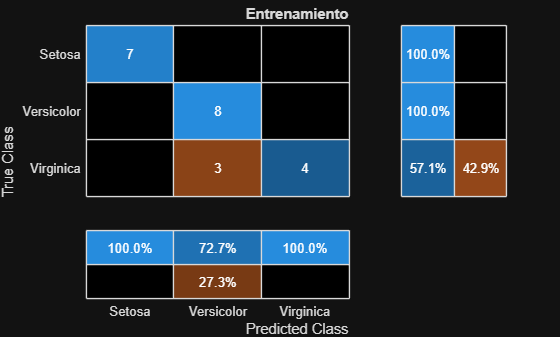

[matrizConEntre,nombreClasesEntre]=confusionmat(claseEntreNum,clasePredichaEntreNum);
confusionchart(matrizConEntre,nomClases,'Title','Entrenamiento','RowSummary','row-normalized','ColumnSummary','column-normalized')

Como los resultados de la clasificación están en formato *dlarray* (en este caso caso *categorical*) hay que extraerlos a un formato *double*.

clasePredichaNum=extractdata(clasePredicha);

Matriz de confusión para las clases predichas con las muestras de **validación**.

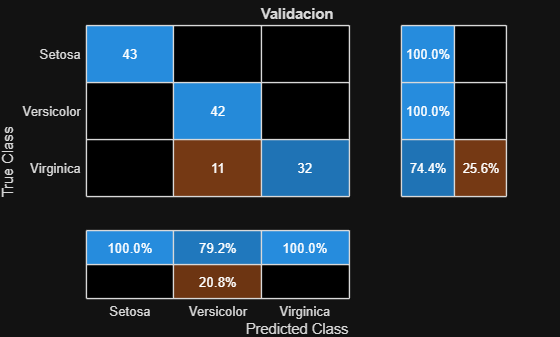

[matrizConVal,nombreClases]=confusionmat(claseValNum,clasePredichaNum);
confusionchart(matrizConVal,nomClases,'Title','Validacion','RowSummary','row-normalized','ColumnSummary','column-normalized')

**EVALUACIÓN DE LA PRECISIÓN GLOBAL**

precisionGlobalEntr=mean(clasePredichaEntre==claseEntreNum);
fprintf("Precisión Global en el entrenamiento: %.2f%%\n", precisionGlobalEntr * 100);

Precisión Global en el entrenamiento: 86.36%


precisionGlobal=mean(clasePredicha==claseValNum);
fprintf("Precisión Global en la validación: %.2f%%\n",precisionGlobal*100);

Precisión Global en la validación: 91.41%


**CÁLCULO DE LOS ÍNDICES DE PRECISIÓN PARA CADA CLASE**

Se calculan las índices siguientes a partir de la matriz de confusión de las predicciones:

- **Recall **=[TP/(TP+FN)], 

- **Precission**= [TP/(TP+FP)], 

- **Accuracy**= [(TP+TN)/(TP+TN+FP+FN)]

- **Specify**= [TN/(TN+FP)], 

- **F1score**= [2*(RECALL*PRECISION)/(RECALL+PRECISION)], 

El significado de cada componente en la matriz de confusión es:

- **TP**(Verdaderos Positivos): Nº casos positivos correctamente clasificados como positivos.

- **FN** (Falsos Negativos): Nº casos positivos incorrectamente clasificados como negativos.

- **FP** (Falsos Positivos): Nº casos negativos incorrectamente clasificados como positivos.

- **TN **(Verdaderos Negativos): Nº casos negativos correctamente clasificados como negativos.

Recall=zeros(numClases,1);
Precission=zeros(numClases,1);
Accuracy=zeros(numClases,1);
Specify=zeros(numClases,1);
F1score=zeros(numClases,1);
numMuestras=sum(matrizConVal(:));

Calculo de índices para cada clase

for i = 1:numClases
    TP=matrizConVal(i, i);
    FN=sum(matrizConVal(i,:))-TP;
    FP=sum(matrizConVal(:,i))-TP;
    TN=numMuestras-TP-FN-FP;
    
    Recall(i)=TP/(TP+FN);
    Precission(i)=TP/(TP+FP);
    Accuracy(i)=(TP+TN)/(TP+TN+FP+FN);
    Specify(i)=TN/(TN+FP);
    F1score(i)=2*(Recall(i)*Precission(i))/(Accuracy(i)+Precission(i));
end
Clase=nomClases;
T= table(Clase,Recall,Precission,Accuracy,Specify,F1score)

T = 3×6 table
        Clase         Recall     Precission    Accuracy    Specify    F1score
    ______________    _______    __________    ________    _______    _______

    {'Setosa'    }          1           1            1           1          1
    {'Versicolor'}          1     0.79245      0.91406     0.87209    0.92874
    {'Virginica' }    0.74419           1      0.91406           1     0.7776
